# Asesoría 14 Setiembre (Repaso de MATLAB)

## Uso de variable simbólica:

Definir una función que dependa de dos variables x e y, y obtener sus derivadas.

syms x y %Define dos variables x, y
f = exp(x*y) - 2*y^2 + 3*x*exp(2*x) % define la función de manera simbólica (no se puede evaluar)

$$f = {\mathrm{e}}^{x\,y}+3\,x\,{\mathrm{e}}^{2\,x}-2\,y^{2}$$

f1 = matlabFunction(f) % Defino a f como función (ya puedo evaluar)

f1 = function_handle with value:
    @(x,y)exp(x.*y)+x.*exp(x.*2.0).*3.0-y.^2.*2.0


f1(2,3) % Usamos f1, porque f1 sí permite evaluar

ans = 713.0177


df_x = diff(f,x) % derivamos respecto a x

$$df\_x = 3\,{\mathrm{e}}^{2\,x}+6\,x\,{\mathrm{e}}^{2\,x}+y\,{\mathrm{e}}^{x\,y}$$

Df_x = matlabFunction(df_x) % covertimos la derivada a función

Df_x = function_handle with value:
    @(x,y)exp(x.*2.0).*3.0+x.*exp(x.*2.0).*6.0+y.*exp(x.*y)



df_y = diff(f,y) % derivamos respecto a x

$$df\_y = x\,{\mathrm{e}}^{x\,y}-4\,y$$

Df_y = matlabFunction(df_y) % covertimos la derivada a función

Df_y = function_handle with value:
    @(x,y)y.*-4.0+x.*exp(x.*y)


Otra forma de definir funciones

f2 = @(x,y) atan(x*y) - exp(4 + x) + 2*log(y)

f2 = function_handle with value:
    @(x,y)atan(x*y)-exp(4+x)+2*log(y)


f2(1,2)

ans = -145.9197


diff(f2,x) % derivada de f2 respecto de x

$$ans = \frac{y}{x^{2}\,y^{2}+1}-{\mathrm{e}}^{x+4}$$

## ¿Puedo evaluar en un vector?

Graficar y = x^2 + 2x en [0,4]

f = @(x) x.^2 + 2.*x % es importante colocar las operaciones con "." pues permite evaluar para un vector

f = function_handle with value:
    @(x)x.^2+2.*x


X = 0:0.1:4; % vector desde 0 hasta 4, avanza en paso 0.1

Y = f(X) % aplica f a cada punto del vector X

Y =          0    0.2100    0.4400    0.6900    0.9600    1.2500    1.5600    1.8900    2.2400    2.6100    3.0000    3.4100    3.8400    4.2900    4.7600    5.2500    5.7600    6.2900    6.8400    7.4100    8.0000    8.6100    9.2400    9.8900   10.5600   11.2500   11.9600   12.6900   13.4400   14.2100   15.0000   15.8100   16.6400   17.4900   18.3600   19.2500   20.1600   21.0900   22.0400   23.0100   24.0000



plot(X, Y, "r") % Cada par ordenado (x,y)
hold on

df = diff(f, x)

$$df = 2\,x+2$$

Df = matlabFunction(df)

Df = function_handle with value:
    @(x)x.*2.0+2.0



Y2 = Df(X)

Y2 =     2.0000    2.2000    2.4000    2.6000    2.8000    3.0000    3.2000    3.4000    3.6000    3.8000    4.0000    4.2000    4.4000    4.6000    4.8000    5.0000    5.2000    5.4000    5.6000    5.8000    6.0000    6.2000    6.4000    6.6000    6.8000    7.0000    7.2000    7.4000    7.6000    7.8000    8.0000    8.2000    8.4000    8.6000    8.8000    9.0000    9.2000    9.4000    9.6000    9.8000   10.0000


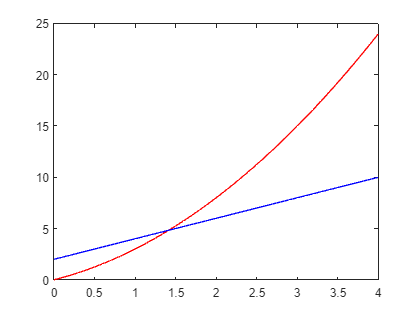


plot(X, Y2, "b")
hold off